## 0. Setting parameters 

clear;close all;
FILE_NAME_BKGD = 'Aug4-0kg-step0.01MeV-nml';
FILE_NAME_SMPL = 'P23-1kg-step0.01MeV-nml';
ENERGY_AXIS = [0.01:0.01:12]';
OUTLIER_THRESHOLD = 3; % times of variance out which the dots are regard as outlier
ACC_STABLE_TIMESTAMP = 150;

ROI.Cl35a = [195-15,195+15]; % Channel in normalized spectrum
ROI.Cl35b = [611-15,611+15];
ROI.Cl35c = [662-15,662+15];
ROI_TITLE.Cl35a = '1.959MeV';
ROI_TITLE.Cl35b = '6.111MeV';
ROI_TITLE.Cl35c = '6.620MeV';

ROI_SELECTED = {'Cl35b','Cl35c'};

% Keep ROIs in ROI_SELECTED
nameTmp = fieldnames(ROI);
for i = 1:length(nameTmp)
    if ~ismember(nameTmp{i},ROI_SELECTED)
        ROI = rmfield(ROI,nameTmp{i});
        ROI_TITLE = rmfield(ROI_TITLE,nameTmp{i});
    end
end
ROI = orderfields(ROI);
ROI_TITLE = orderfields(ROI_TITLE);
ROI_NAMES = fieldnames(ROI_TITLE);
TEST_DETECTION_TIME = [1,2,5,10,30]; % Unit: detection time of one ".spe" file
N_ROC_POINT = 500;

## 1. Import data and data pre-processing 

### 1.1 Import

bkgd = loadnormalizedseq(FILE_NAME_BKGD);
if isequal(bkgd,-1)
    error('Error: Normalized background file can not be read');
end
smpl = loadnormalizedseq(FILE_NAME_SMPL);
if isequal(smpl,1)
    error('Error: Normalized sample file can not be read');
end

### 1.2 Pre-processing

bkgd = deleteoutlier(bkgd,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);

smpl = deleteoutlier(smpl,ACC_STABLE_TIMESTAMP,ROI,OUTLIER_THRESHOLD,0);

### 1.3 Show spectra with and without illicit objects

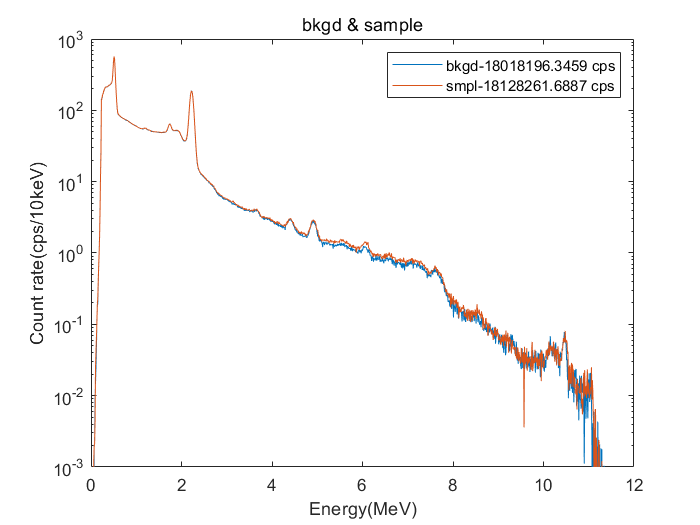

figure;
semilogy(ENERGY_AXIS,[sum(bkgd,2),sum(smpl,2)]/size(bkgd,2));hold on;
xlabel('Energy(MeV)');
ylabel(['Count rate(cps/',num2str(1000*(ENERGY_AXIS(2)-ENERGY_AXIS(1))),'keV)']);
legend(['bkgd-', num2str(sum(sum(bkgd))),' cps'], ...
    ['smpl-',num2str(sum(sum(smpl))),' cps']);
xlim([0 12]);ylim([1e-3 1e3]);
title('bkgd & sample');
hold off;

## 2. Dot Cloud Method

REMEMBER: Everything here is trying to transport a list of spectra into a list of VALUABLE index. 

DO NOT THINK COMPLICATED

Input parameters here:

normalized spectrums - `bkgd/smpl`

Region of interest - `ROI/ROI_TITLE`

Following is data processing core.

### 2.1 Dot cloud figure and index

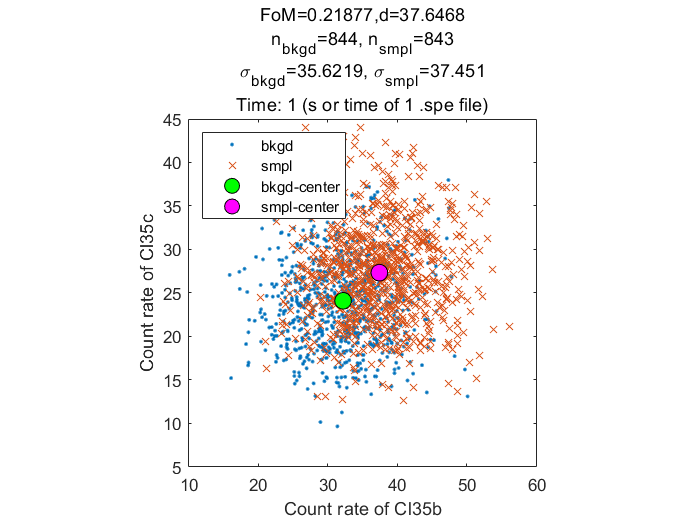

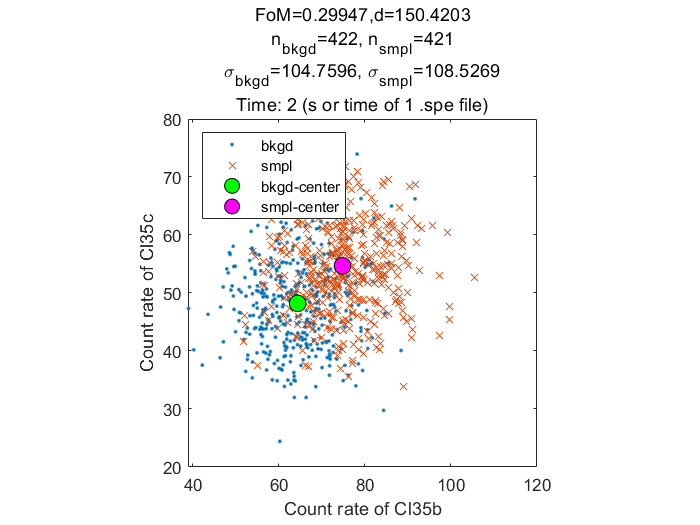

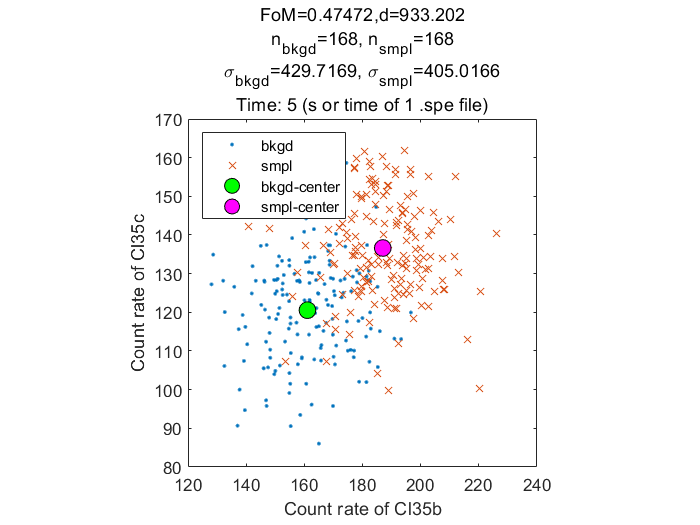

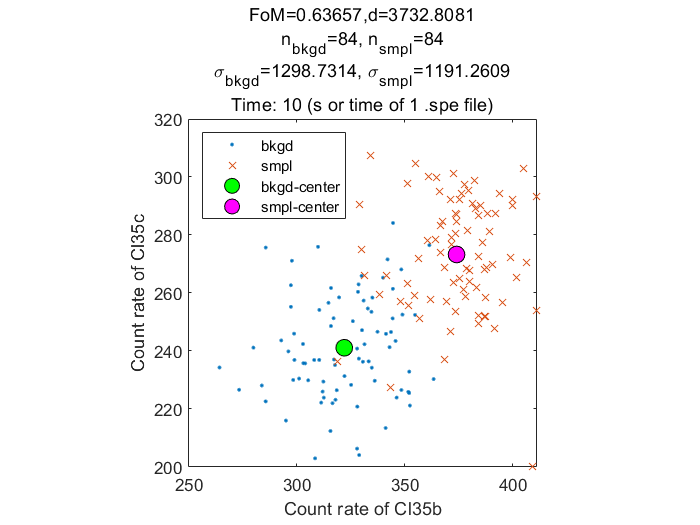

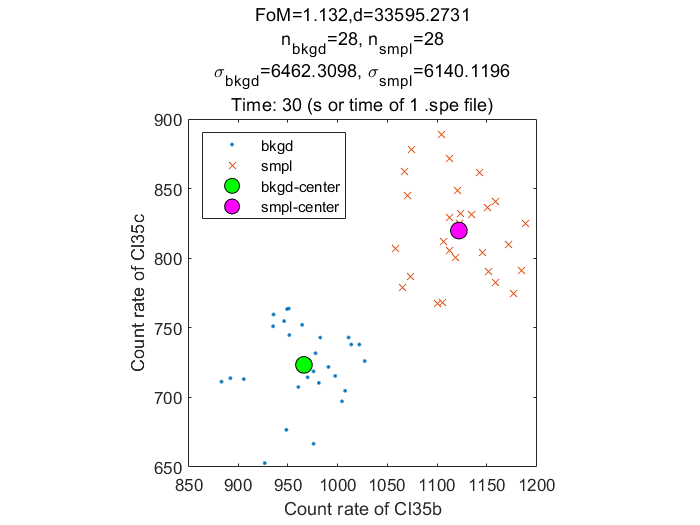

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    bkgdDots{iTime,1} = dotlist(bkgd,iTime,ROI);
    smplDots{iTime,1} = dotlist(smpl,iTime,ROI);
    discParam = cclFoM(bkgdDots{iTime,1},smplDots{iTime,1});
    coreIndex{iTime,1} = discParam.index1;
    coreIndex{iTime,2} = discParam.index2;
    switch length(fields(ROI))
        case 2
            figure;
            plot(bkgdDots{iTime,1}(1,:),bkgdDots{iTime,1}(2,:),'.');hold on;
            plot(smplDots{iTime,1}(1,:),smplDots{iTime,1}(2,:),'x');
            % Plot cloud center
            plot(discParam.center1(1),discParam.center1(2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','g');% Green for dataSet1
            plot(discParam.center2(1),discParam.center2(2),'o','MarkerSize',10,'MarkerEdgeColor','k','MarkerFaceColor','m');% Pink for dataSet2
            xlabel(['Count rate of ',ROI_NAMES{1}]);
            ylabel(['Count rate of ',ROI_NAMES{2}]);
            title({['FoM=',num2str(discParam.FoM),',d=',num2str(discParam.dis),]; ...
                ['n_b_k_g_d=',num2str(size(bkgdDots{iTime,1},2)), ...
                ', n_s_m_p_l=',num2str(size(smplDots{iTime,1},2))];
                ['\sigma_b_k_g_d=',num2str(std(discParam.index1,1)), ...
                ', \sigma_s_m_p_l=',num2str(std(discParam.index2,1))]; ...
                ['Time: ',num2str(iTime),' (s or time of 1 .spe file)']});
            legend('bkgd','smpl','bkgd-center','smpl-center','Location','northwest');
            axis square;
            hold off;
        otherwise
            disp('Notice: Can not plot ROI~=2 yet');
    end
end

## 2.2 Dot cloud ROC

### 2.2.1 seperation according to orginal index

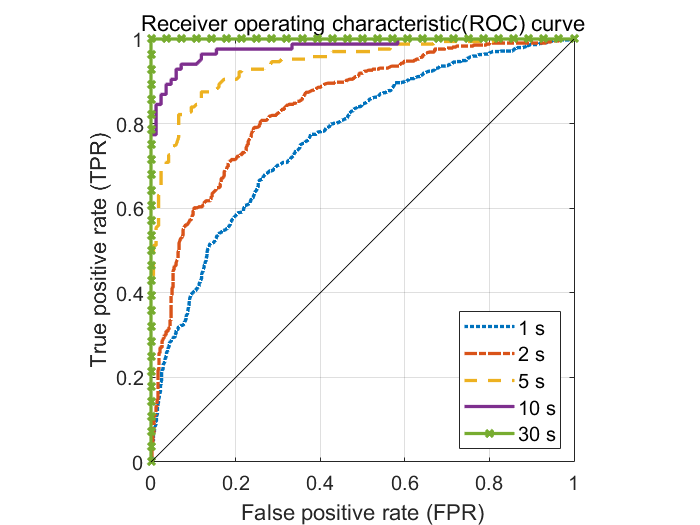

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    rocRaw{iTime,1} = rocraw(coreIndex{iTime,1},coreIndex{iTime,2},N_ROC_POINT);
end
handle = plotroccurves(rocRaw,TEST_DETECTION_TIME);

### 2.2.2 seperation according to gauss distribution

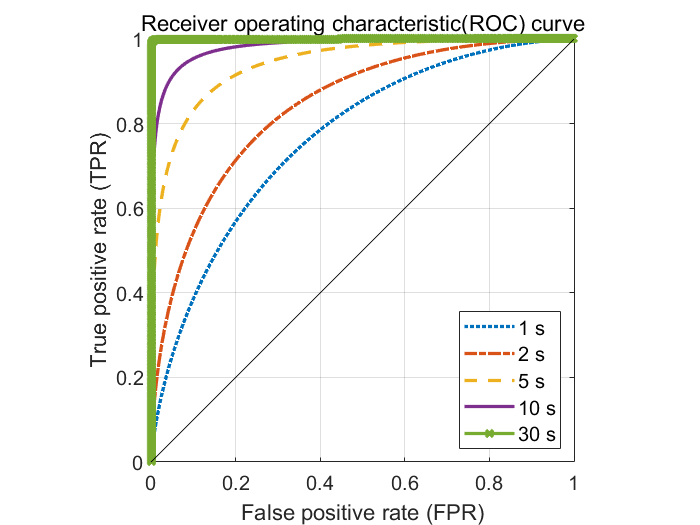

for iTime = TEST_DETECTION_TIME % Unit: detection time of one ".spe" file
    rocGauss{iTime,1} = rocgauss(coreIndex{iTime,1},coreIndex{iTime,2},N_ROC_POINT);
end
handle = plotroccurves(rocGauss,TEST_DETECTION_TIME);

## 3. 计算最优投影方向

### 3.1 1s谱最优投影方向